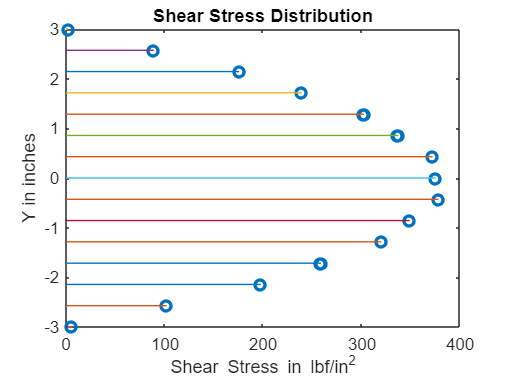

shear = table2array(readtable("shear_stress","Range","A2:E6282"));
[r,c]=size(shear);
profile_s=zeros(r,2);
for i=1:r
    if(shear(i,2)==16.286)
        profile_s(i,1)=shear(i,3);
        profile_s(i,2)=shear(i,5);
    else
        profile_s(i,1)=NaN;
        profile_s(i,2)=NaN;
    end
end
plot(profile_s(:,2),profile_s(:,1),'o',"LineWidth",2);
for i=1:r
    if(~isnan(profile_s(i,1)))
        hold on
        plot([0 profile_s(i,2)], [profile_s(i,1) profile_s(i,1)])
    end
end
xlabel("Shear Stress in lbf/in^2");
ylabel("Y in in");
title("Shear Stress Distribution")
hold off;

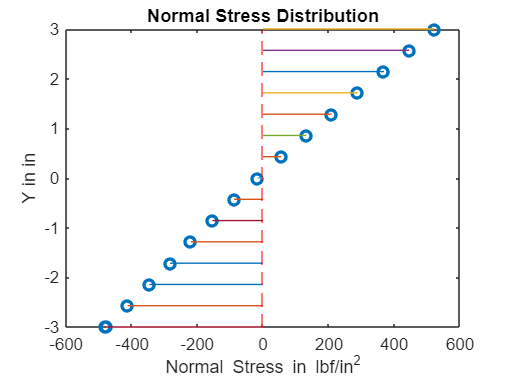

normal = table2array(readtable("normal_stress","Range","A2:E6282"));
profile_n=zeros(r,2);
for i=1:r
    if(normal(i,2)==18)
        profile_n(i,1)=normal(i,3);
        profile_n(i,2)=normal(i,5);
    else
        profile_n(i,1)=NaN;
        profile_n(i,2)=NaN;
    end
end
plot(profile_n(:,2),profile_n(:,1),'o',"LineWidth",2);
xline(0,'--r');
for i=1:r
    if(~isnan(profile_n(i,1)))
        hold on
        plot([0 profile_n(i,2)], [profile_n(i,1) profile_n(i,1) ])
    end
end
xlabel("Normal Stress in lbf/in^2");
ylabel("Y in in");
title("Normal Stress Distribution")
hold off;